# 画图篇

`    将数据、结果呈现出来是一件非常重要的事情，图片能够非常直观的表达结果。接下来我会介绍一些常用的画图方法。`

## `常用画图函数`

### `折线图`

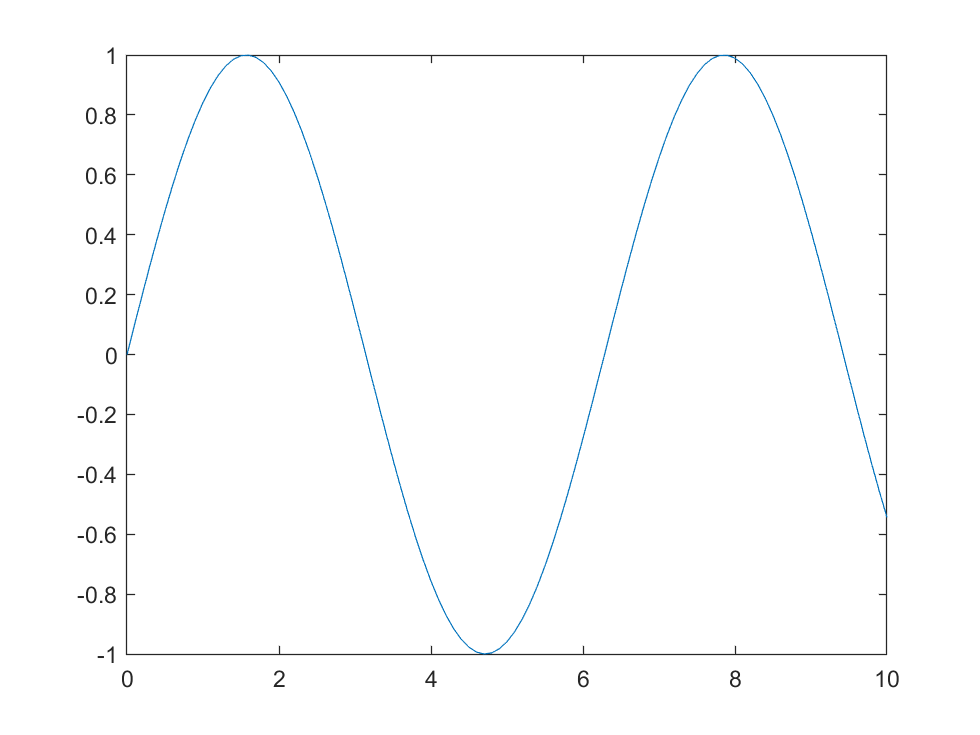

% x轴数据
t = 0:0.1:10;
% y轴数据
y = sin(t);
plot(t,y);

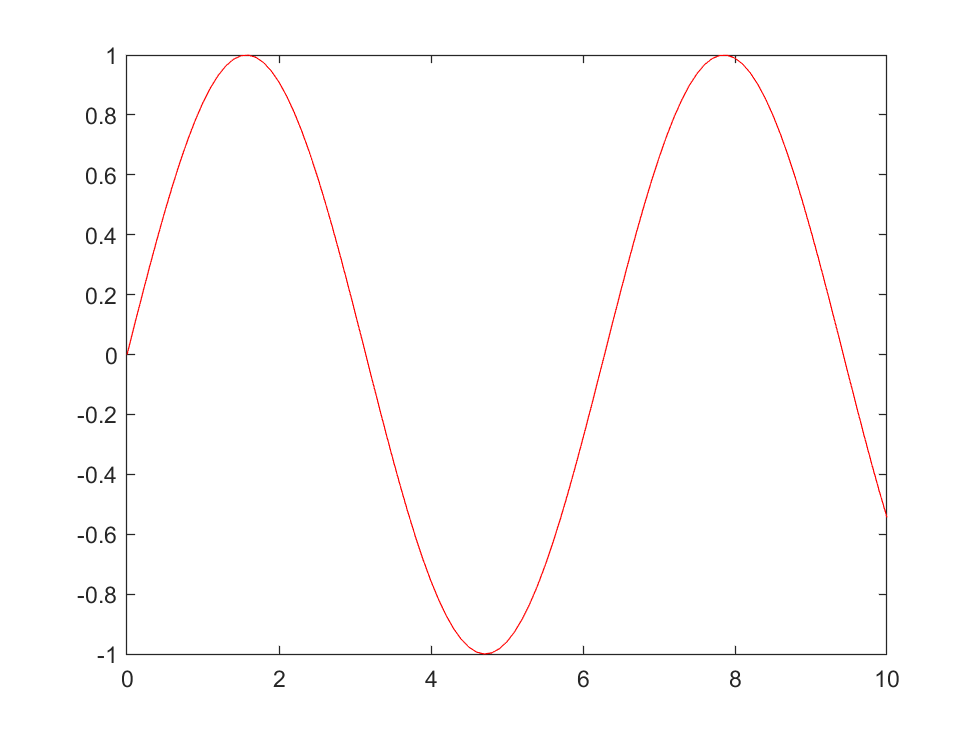

% 画红色的线
plot(t,y,'color','r');

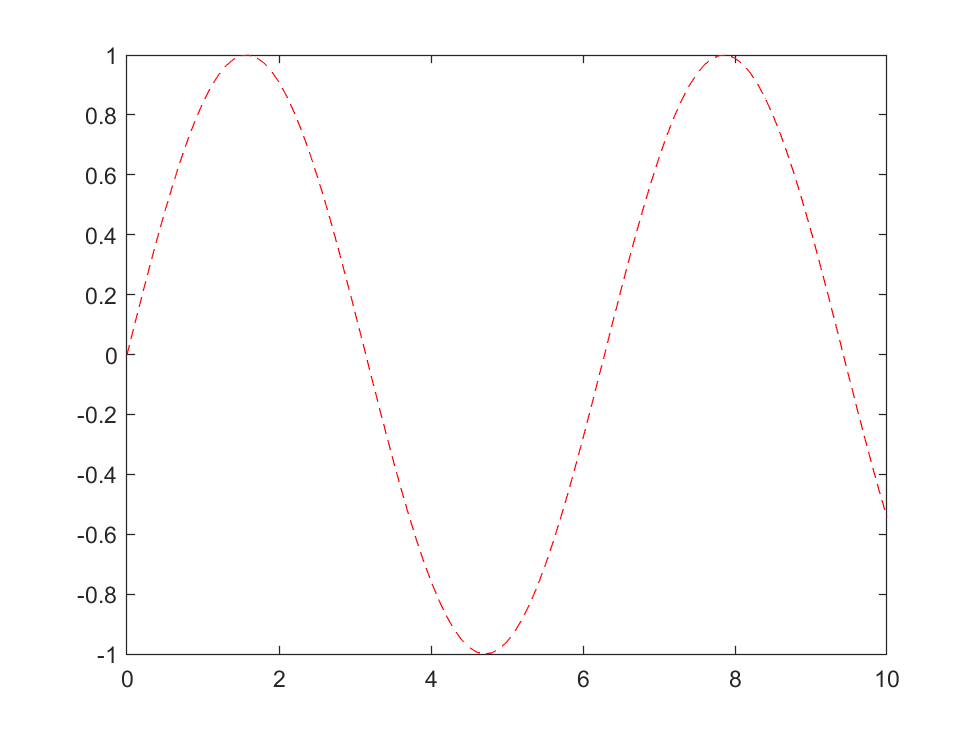

% 画红色的虚线
plot(t,y,'color','r','LineStyle','--');

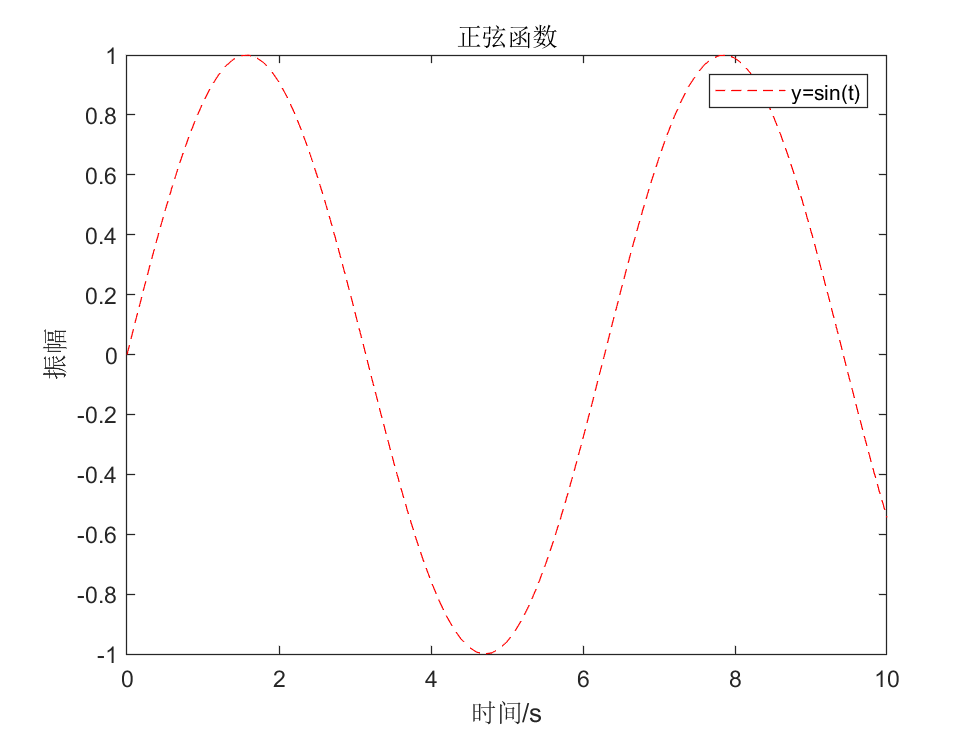

% 添加x轴、y轴label，添加标题，添加legend。
plot(t,y,'color','r','LineStyle','--');
xlabel('时间/s');
ylabel('振幅');
title('正弦函数');
legend('y=sin(t)');

plot默认会清空当前坐标轴之前的数据，我们可以使用hold on进行保持。

t = 0:0.1:10;
y = sin(t);
plot(t,y)

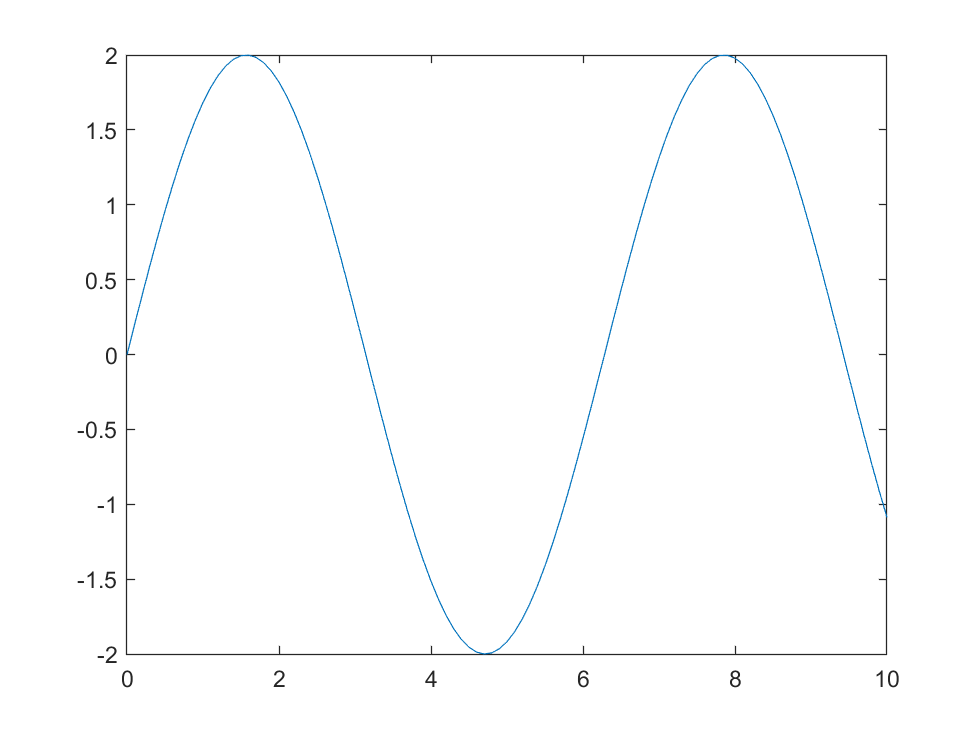

plot(t,2*y)

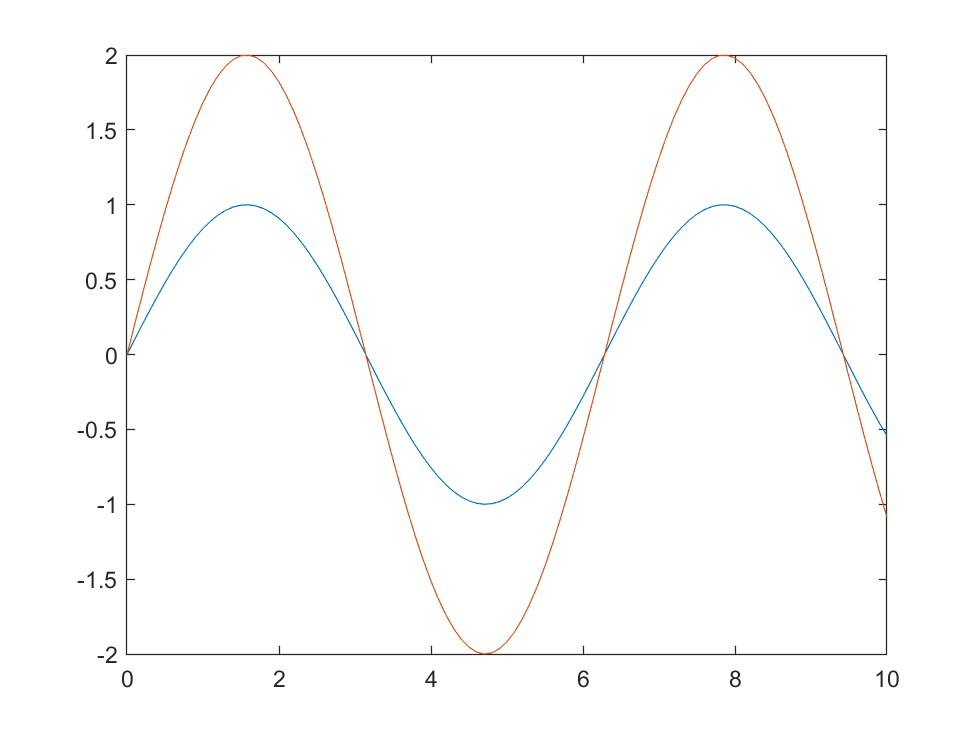

plot(t,y)
% 使用hold on让plot不清除之前的数据
hold on
plot(t,2*y)
hold off

subplot 一个窗口画多幅图

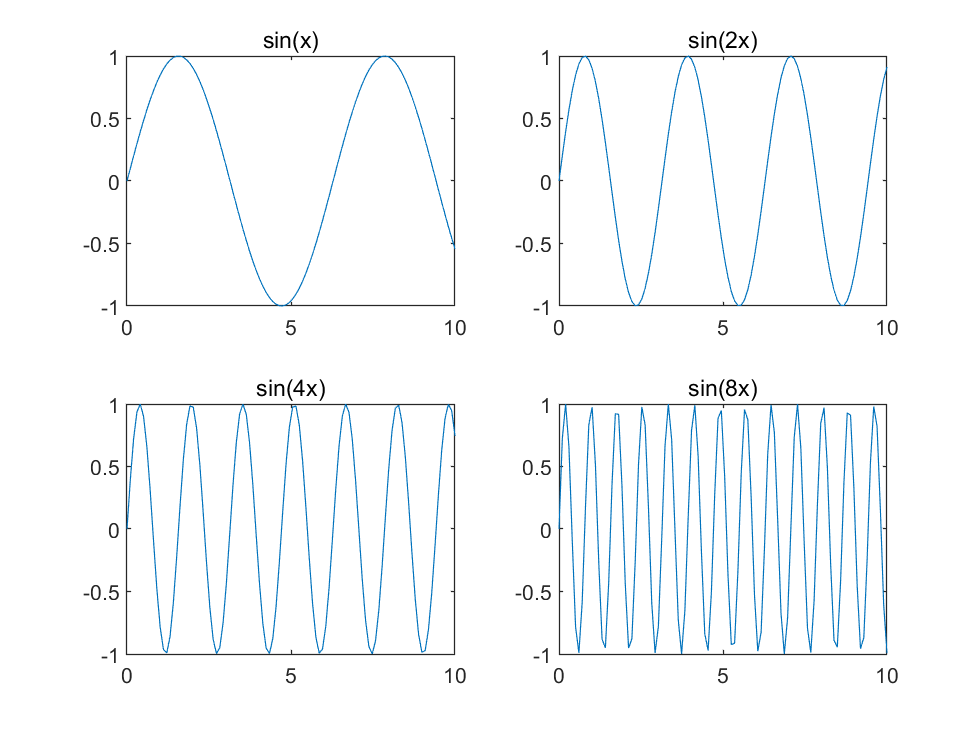

subplot(2,2,1)
x = linspace(0,10);
y1 = sin(x);
plot(x,y1)
title('sin(x)')

subplot(2,2,2)
y2 = sin(2*x);
plot(x,y2)
title('sin(2x)')

subplot(2,2,3)
y3 = sin(4*x);
plot(x,y3)
title('sin(4x)')

subplot(2,2,4)
y4 = sin(8*x);
plot(x,y4)
title('sin(8x)')

新建窗口进行画图

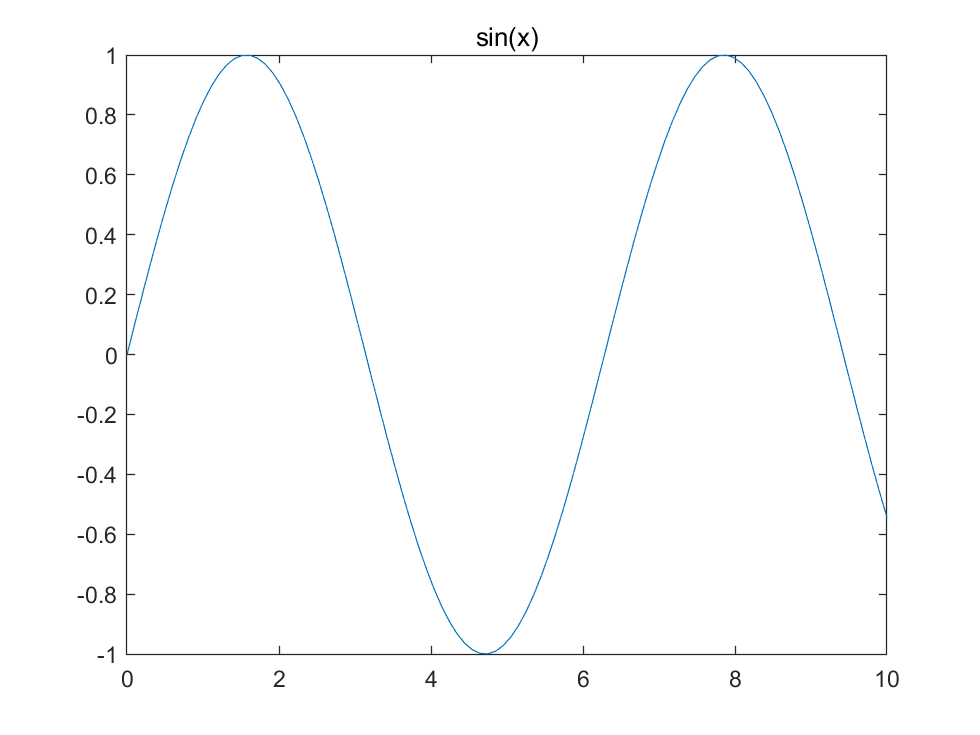

x = linspace(0,10);

figure
y1 = sin(x);
plot(x,y1)
title('sin(x)')

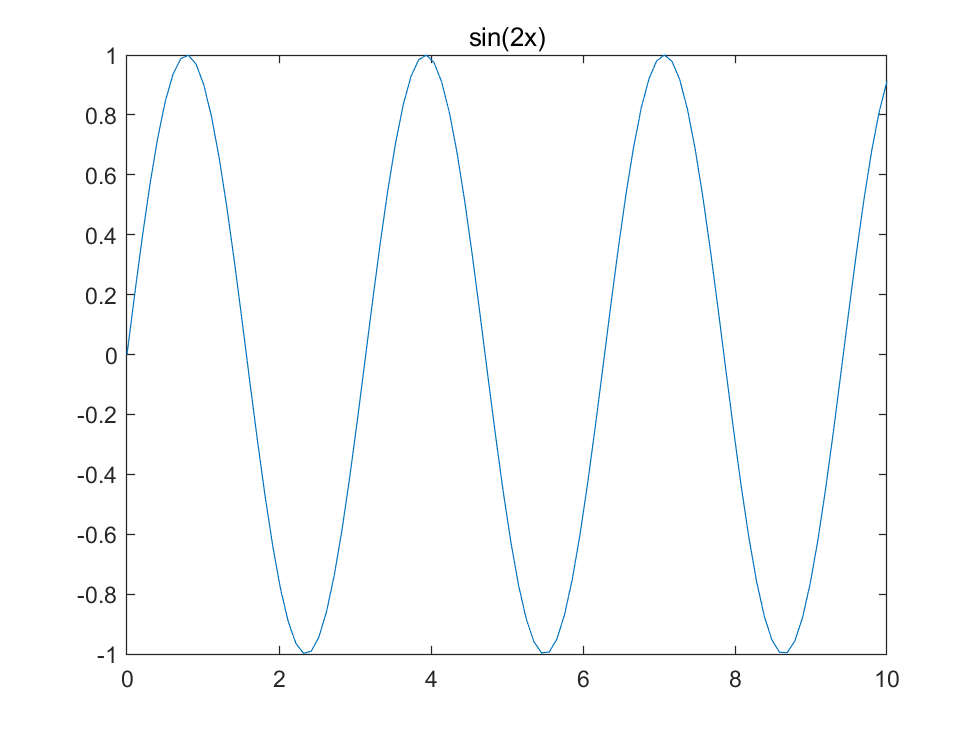

figure
y2 = sin(2*x);
plot(x,y2)
title('sin(2x)')

### 散点图

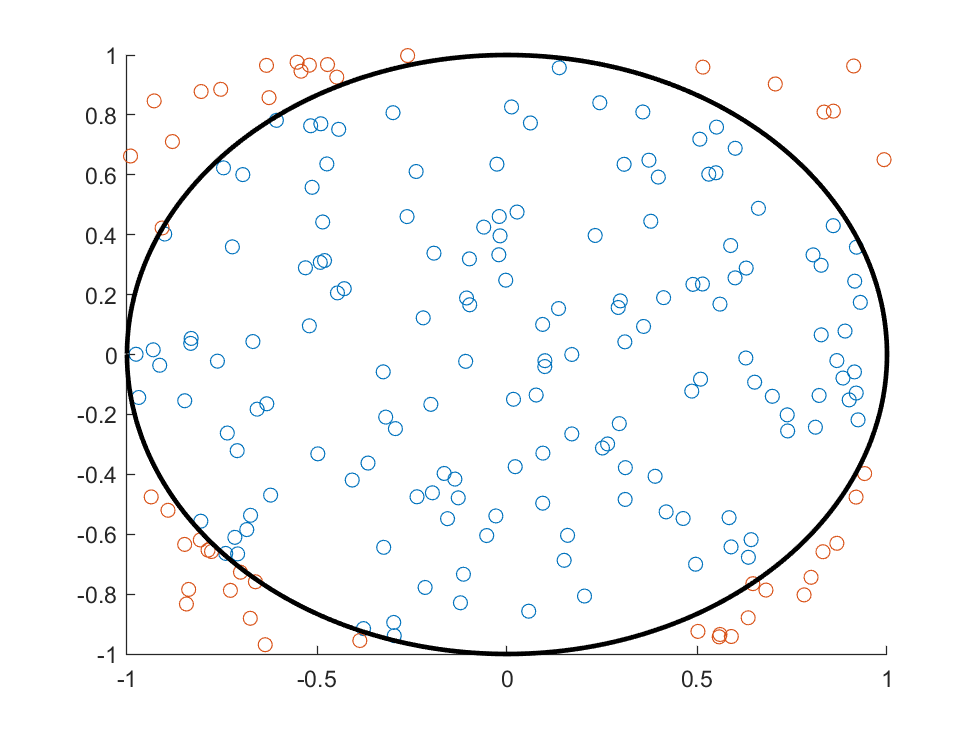

% 定义多少个点
N = 200;
% rand生成[0,1)的随机数， 2*rand(1,N)-1表示[-1,1)内的随机数
x = 2*rand(1,N)-1;
y = 2*rand(1,N)-1;
% 找出哪些点在圆内，哪些在圆外
in = x.^2 + y.^2 <= 1;
out = ~in;
% 锁住图形
hold on;
% 画散点图
scatter(x(in),y(in));
scatter(x(out),y(out));
% % 也可以使用plot函数画散点图
% % plot(x(in),y(in),'linestyle','none','marker','o');
% % plot(x(out),y(out),'linestyle','none','marker','o');
% 画圆
plot(cos(-pi:0.01:pi),sin(-pi:0.01:pi),'k','linewidth',2);

### `饼图`

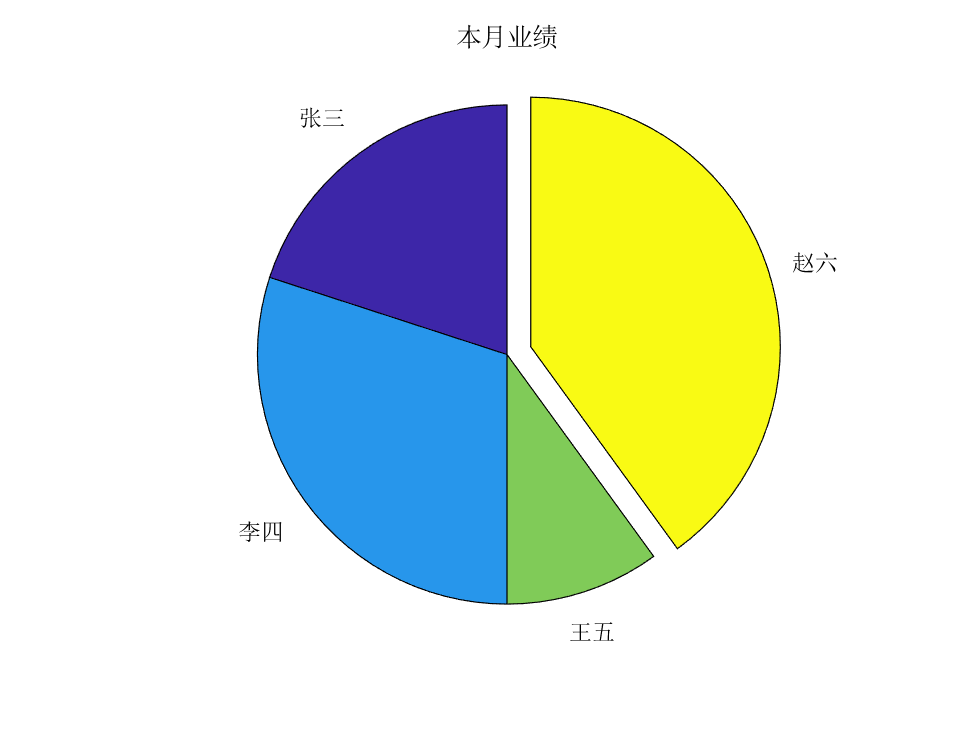

% 饼的名字
labels = {'张三','李四','王五','赵六'};
% 饼的大小
X = [10000, 15000, 5000, 20000];
% 哪一块饼要分离出来
explode = [0 0 0 1];
% 画饼图
pie(X,explode,labels);
title('本月业绩');

### 其他图

matlab的画图函数实在是太多太多了，如柱状图bar、直方图histogram等等，甚至还可以创建文字云图wordcloud！

但是在这里我就不为大家一一讲解，需要用到的时候大家可以查看文档，因为文档说明比我说的还详细。

大家可以搜索"图形"，然后找到自己所需要的画图函数。

## 图片

#### 伪彩色

通过映射的方法进行上色。

使用colormap函数定义映射表。

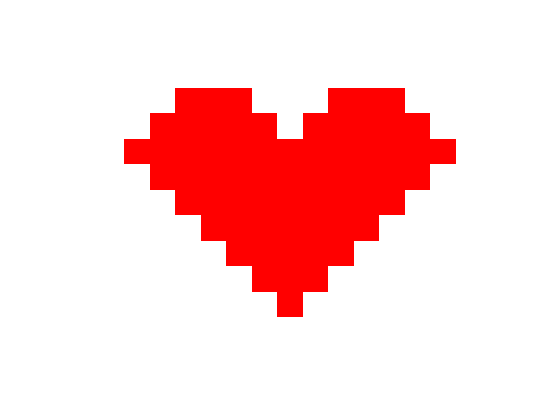

% 伪彩色，不是真实的颜色。
img = ones(11,17);
img(2,[5,6,7,11,12,13]) = 2;
img(3,[4,5,6,7,8,10,11,12,13,14]) = 2;
img(4,3:15) = 2;
img(5,4:14) = 2;
img(6,5:13) = 2;
img(7,6:12) = 2;
img(8,7:11) = 2;
img(9,8:10) = 2;
img(10,9) = 2;
image(img);
% 定义映射关系
colormap([1,1,1;1,0,0]);
axis image
axis off

#### 真彩色

通过RGB进行上色。

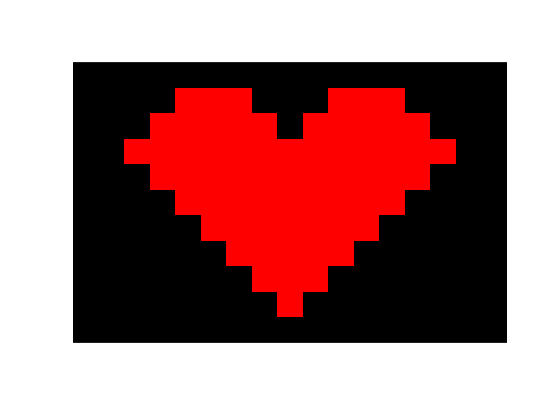

% 真彩色，使用rgb的方法绘制
% 取值范围在0~1之间。
img = zeros(11,17,3);
img(2,[5,6,7,11,12,13],1) = 1;
img(3,[4,5,6,7,8,10,11,12,13,14],1) = 1;
img(4,3:15,1) = 1;
img(5,4:14,1) = 1;
img(6,5:13,1) = 1;
img(7,6:12,1) = 1;
img(8,7:11,1) = 1;
img(9,8:10,1) = 1;
img(10,9,1) = 1;
% 绘制图像
image(img);
axis image
axis off

## 句柄

    句柄是什么？句柄是对象的ID，通过这个ID我们可以操纵对象。比如获取属性值或者修改属性。

    比如说，我画一条折线图。

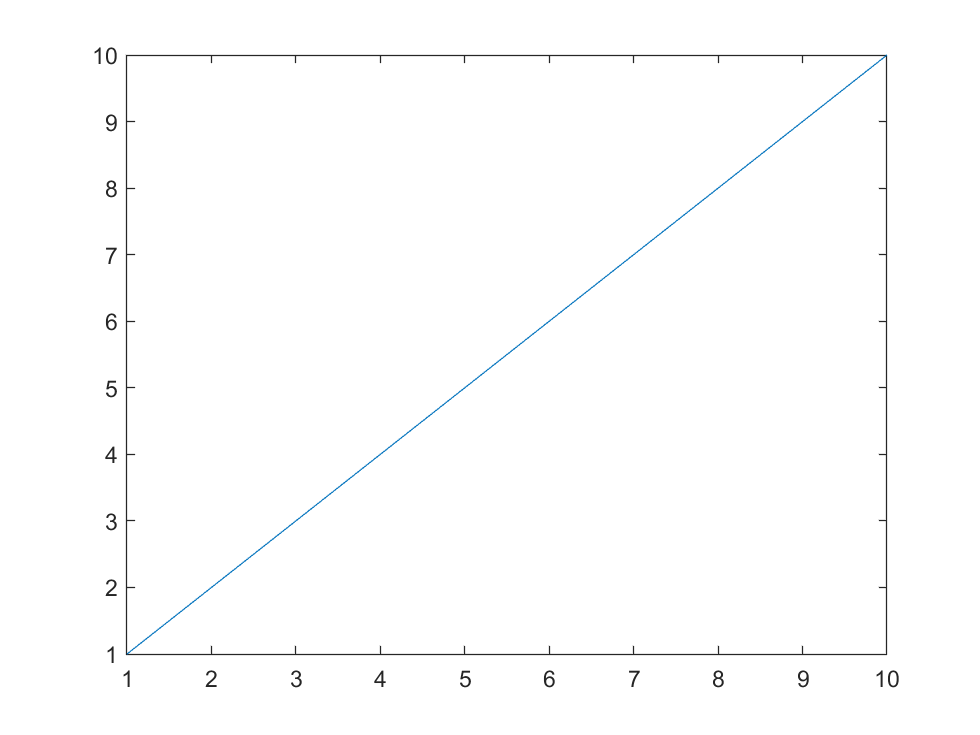

% 所有画图函数都会返回一个句柄，代表所画的这个对象。
h_line = plot(1:10, 1:10);

    可以直接通过句柄对这条曲线进行属性修改，比如颜色、宽度、样式等等进行修改。

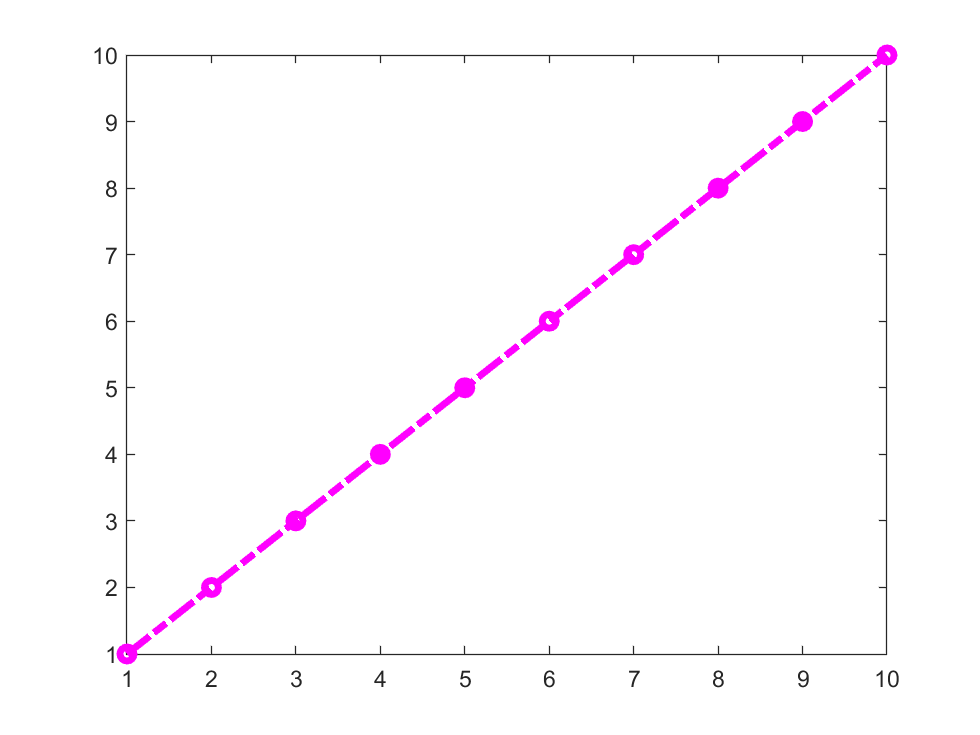

set(h_line,'linewidth',3,'linestyle','-.','marker','o','color','m');

    对句柄操作最常用的是set和get函数，set是设置属性，get是获取属性。

% 获取线的x轴数据
x = get(h_line,'xdata')

x =      1     2     3     4     5     6     7     8     9    10


set和get函数是早期matlab设置和获取属性值的方法，新版本matlab开始支持.属性的方式进行查询或者修改属性。

x = h_line.XData

x =      1     2     3     4     5     6     7     8     9    10


注意到我写的是h_line.XData，而get(h_line,'xdata')写的是xdata，是这样的，如果使用函数的方式，属性值不区分大小写，甚至可以不写全，我写成get(h_line,'xda')也是可以的，matlab会自动补全。而结构体的方式则必须要区分大小写。

第三种修改和查看的方式：gui界面

双击工作区的 会弹出下面的界面（此界面是2018的新界面，之前的版本界面没有分组的）

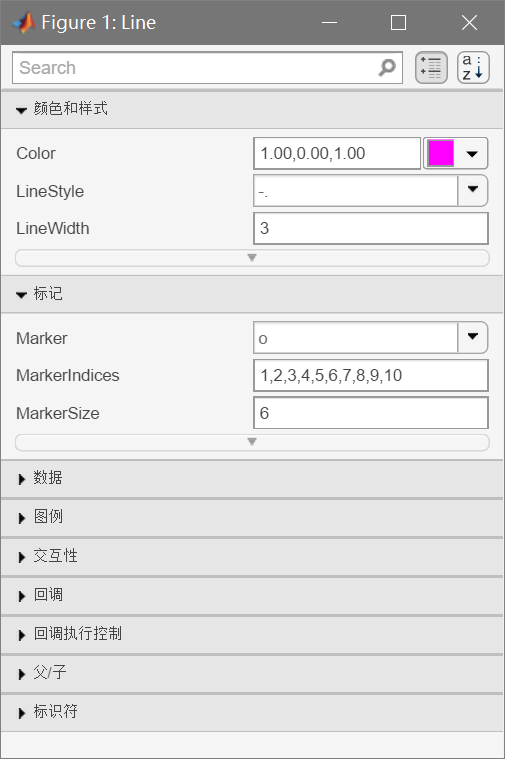

可以看到我可以直接通过界面交互的方式进行修改值。

## 动画

### pause

暂停一次，暂停期间其他任何事情都不能做。在命令行窗口按ctrl+c终止

### 定时器

后台计时，每隔设定好的时间后执行一次。可以暂停然后继续运行。

    使用方法：

响应函数（或称回调函数）就是当你做了什么动作之后，比如点击鼠标，键盘敲入，点击按钮等等就会运行的函数。在这里指的是定时器到点时运行的函数。

定时器这里的响应函数是指每次计时结束后执行的函数。

使用定时器虽然可以在后台执行，但也有一个缺点，那就是不能返回结果，不过我们可以使用global定义全局变量进行数据的更新。

## 层级关系

窗口(figure)->坐标轴(axes)->曲线、图片

一些常用的函数：

h = figure 创建窗口，并返回句柄

h = axes 创建坐标轴，并返回句柄

h = gcf 获取当前活动的窗口句柄，如没有则创建一个

h = gca 获取当前活动的坐标轴句柄，如没有则创建一个

plot(h_axes, x, y) 指定在h_axes坐标轴上画线。

plot(x,y)它等效于plot(gca,x,y)，所以可以不用新建一个窗口，直接使用

plot(figure, x,y)会报错，因为它不是figure的子级。